# Ejercicios raíces

## Segmento de un círculo

Un segmento de un círculo es la porción de un círculo limitada por una cuerda y el arco correspondiente (ve la zona sombreada de la figura abajo). Si r es el radio del círculo y θ el ángulo el ángulo central, entonces el área A del segmento está dada por


$$A=\frac{1}{2}r^2 \left(\theta -\sin \left(\theta \right)\right)$$


donde θ está dado en radianes. 

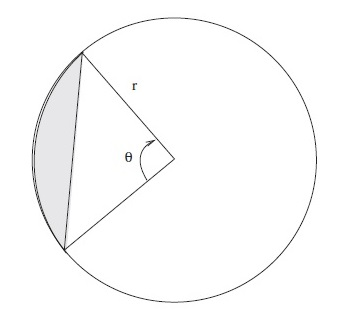

Grafica el área en el intervalo [0, 2*pi] radianes, para un círculo de radio $r=1$.

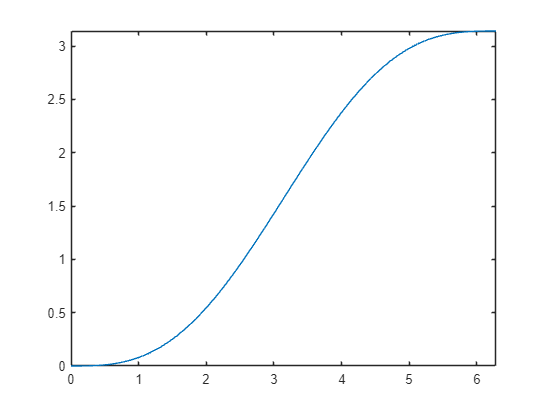

r = 1;
f = @(theta) 1/2*r^2.*(theta - sin(theta));
fplot(f, [0 2*pi])

Encuentra para que ángulo $\theta$ el área del segmento circular vale 1.

Utiliza el método de bisección. ¿En cuántas iteraciones converge?

g = @(x) f(x) - 1;

[root, iterations] = bisection(g, 1, 3);
fprintf('Biseccion - raiz: %1.6f - iteraciones: %d', root, iterations)

Biseccion - raiz: 2.554196 - iteraciones: 53

¿Cuánto vale el ángulo encontrado en grados?

ang = root/pi*180;
fprintf('%3.2f', ang)

146.34

Utiliza el método de Newton-Raphson.  ¿En cuántas iteraciones converge?

[root, iterations] = newtonRaphson(g, 2);
fprintf('Newton-Raphson - raiz: %1.6f - iteraciones: %d', root, iterations)

Newton-Raphson - raiz: 2.554196 - iteraciones: 5

## Tanque esférico de radio R

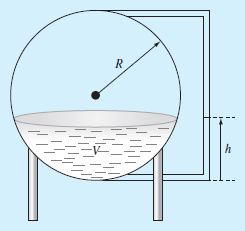


$$V\left(h\right)=\pi h^2 \left(\frac{3R-h}{3}\right)$$


Queremos encontrar h tal $V=V_d$ deseada

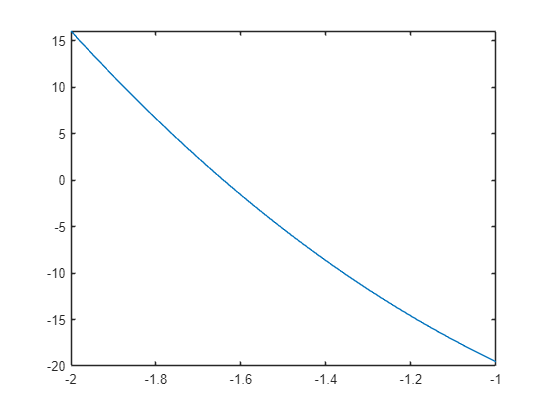

Vd = 30;
R = 3;
v = @(h) pi.*h.^2.*((3*R-h)./3);

f = @(h) v(h) - Vd;
fplot(f, [-2 -1])

[root, iterations] = newtonRaphson(f, -1.6);
fprintf('Newton-Raphson - raiz: %1.6f - iteraciones: %d', root, iterations)

Newton-Raphson - raiz: -1.640812 - iteraciones: 4

## Bungee jumper 

Determina la masa máxima que puede tener un saltador si, por motivos de seguridad, la velocidad no puede exceder de 33m/s a los 4s. 


$$v=\sqrt{g\frac{m}{c_d }\;}$$

$$\tanh \left(\sqrt{g\frac{c_d }{m}}\;t\right)$$


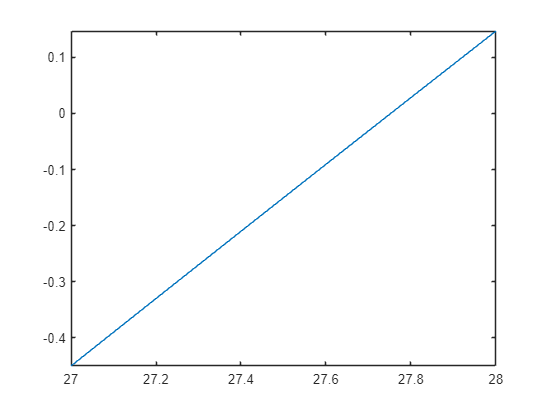

g = 9.81;
cd = 0.25;
vM = 33;
t = 4;
v = @(m) sqrt(g.*m./cd).*tanh(sqrt(g.*m./cd.*t));

f = @(m) v(m) - vM;
fplot(f, [27 28])

[root, iterations] = newtonRaphson(f, 27);
fprintf('Newton-Raphson - raiz: %1.6f - iteraciones: %d', root, iterations)

Newton-Raphson - raiz: 27.752294 - iteraciones: 3

## Principio de Arquímedes y una esfera de radio r

De acuerdo con el principio de Arquímedes, la **fuerza de flotación** es igual al **peso del fluido desplazado** por la porción sumergida de un objeto. Para la esfera de corcho ilustrada en la siguiente figura, usa el método de bisección para determinar la altura h de la porción que queda encima del agua. Utiliza los siguientes valores para tu cálculo: r = 1m, densidad de la esfera ρe = 200kg/m3 y densidad del agua ρa= 1000kg/m3. Observa que el volumen de la porción de la esfera por encima del agua se puede calcular mediante

 
$$V=\frac{\pi h^2 }{3}\left(3r-h\right)$$


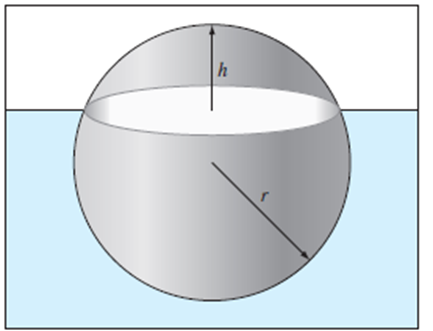

Para estar en equilibrio, la fuerza de flotación (que depende de h) debe ser igual al peso total de la esfera. Recuerda que F=mg y m=ρV. Por lo tanto, F = ρVg.

¿Peso de la esfera? ¿Volumen sumergido (desplazado)? ¿Fuerza de flotación? En equilibrio la fuerza total es cero. 

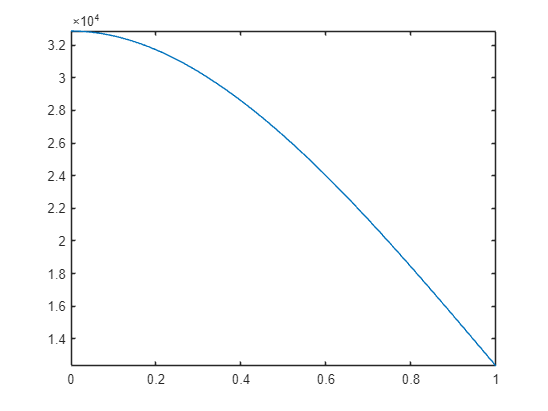

pe = 200;
pa = 1000;
r = 1;
g = 9.81;

v = 4/3*pi*r^3;
ve = @(h) pi.*h.^2./3.*(3*r - h);
vs = @(h) v - ve(h);
fb = @(h) pa*vs(h)*g;
we = pe*v*g;
f = @(h) fb(h) - we;
fplot(f, [0 1])


[root, iterations] = newtonRaphson(f, 0.8);
fprintf('Newton-Raphson - raiz: %1.6f - iteraciones: %d', root, iterations)

Newton-Raphson - raiz: 1.425719 - iteraciones: 4

fprintf('Peso de la esfera = %f', we)

Peso de la esfera = 8218.406382

fprintf('Volumen sumergido = %f', vs(root))

Volumen sumergido = 0.837758

fprintf('Fuerza de flotacion = %f', fb(root))

Fuerza de flotacion = 8218.406382

A certain nonlinear spring develops a restoring force given by


$$F=c_1 x+c_3 x^3 +c_5 x^5$$


where F is in kg force and x is in cm. The values of the constants are

$c_1$ = 5.25 kg/cm,

$c_3$  = 0.60 kg/cm,

$c_5$  = 0.0118 kg/cm.

If a 12.5 kg weight is placed on the spring, how far will it compress?